#### Load EEG data. Right now we are looking at subject 1.

load("subj01-alldata.mat");

### Glove Data

The GloveData is a 18x1024x234 matrix. Each of the 18 rows is the data for a particular sensor.

Notice that 1024 is 8192/8. This may come in handy later as we try to plot glove data against time.

#### Let's plot the glove data for the first sensor.

%let's show all the labels of the EEG struct for easy viewing
EEG

%what is the first sensor?
EEG.channels_glove(1,:)

ans = 'Thumb_Roll     '

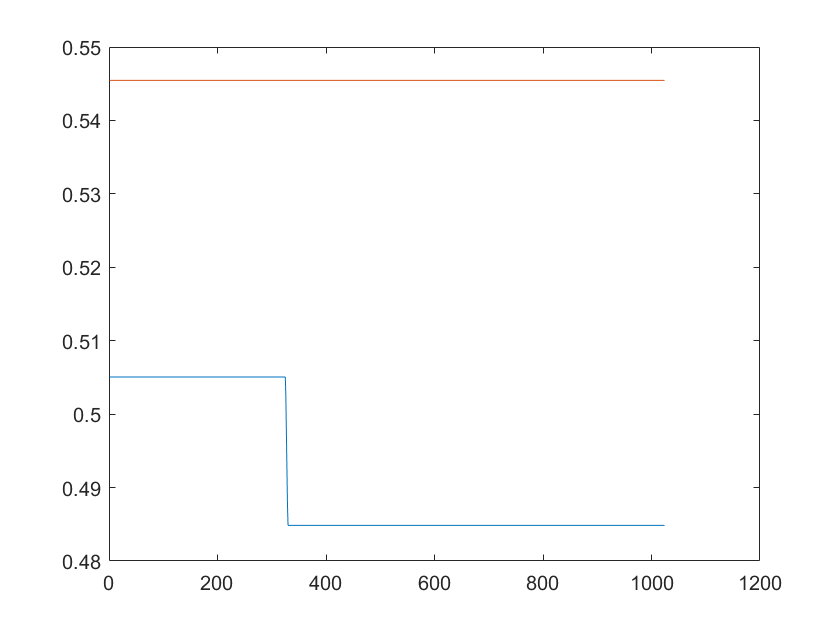


%now let's plot
%we need to save the first set
sensor1 = EEG.glovedata(1,:,:);

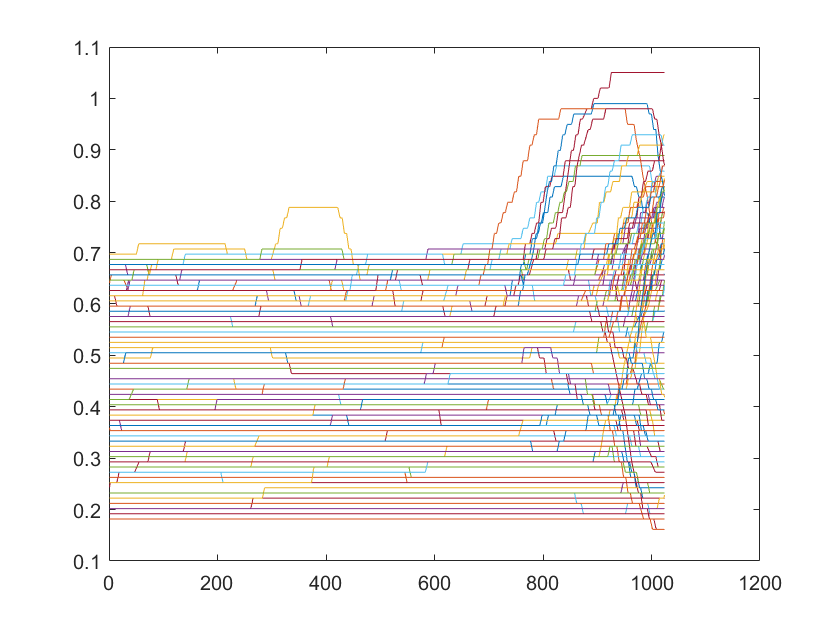

%trial cases 
%plot all the data for the thumb roll sensor for trial 1
figure(1)
plot(sensor1(:,:,1))
hold on;
%plot all the data for the thumb roll sensor for trial 2
plot(sensor1(:,:,2))
hold off;

From these visualizations of the first two trials, we can better understand what the data is showing. Each trial, the person is asked to make different hand positions. So that is why trial 1 and trial 2 have different values for the thumb roll. 

%let's see what happens if we plot all the thumb roll values for each trial
%on the same graph.
figure(2)
for i=1:234
    plot(sensor1(:,:,i))
    hold on;
end
hold off;

Now, while this seems to make sense, this isn't very useful.

#### Let's plot the glove data for all the sensors for the first trial.

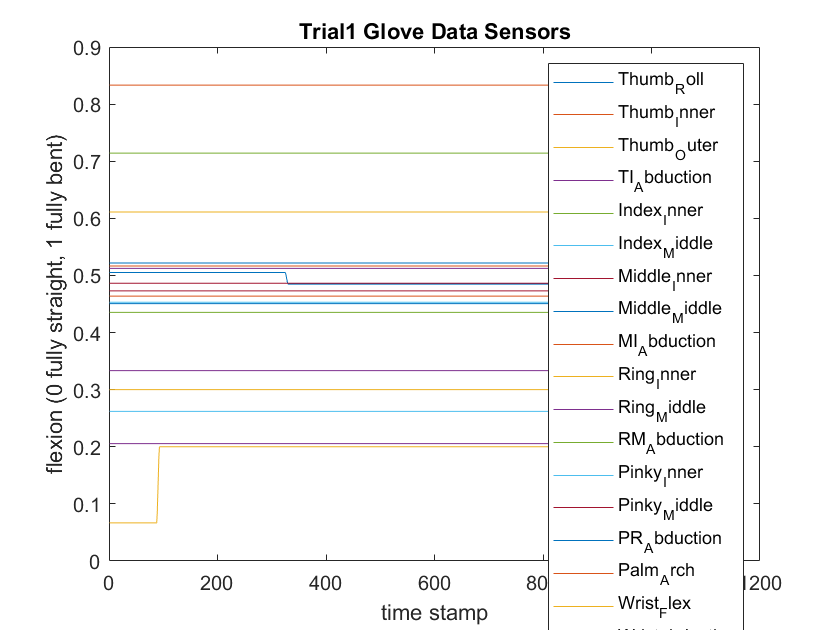

trial1 = EEG.glovedata(:,:,1);
figure(3)
for i=1:18
    plot(trial1(i,:,:))
    hold on;
end

hold off;
%let's add lables so we can try to understand what is happening
title('Trial1 Glove Data Sensors')

ans = categorical
     point 


xlabel('time stamp') 
ylabel('flexion (0 fully straight, 1 fully bent)')
legend(EEG.channels_glove)

%let's see what the performed movement was
EEG.movement(:,1)

Clearly this isn't very helpful either. What if we try to get one value from each of the "segments of the hand?"

Before we go too far, we should also explore how this data relates to the other dataset. Let's reference the SEEDS paper.